# Sesión 6: Modelamiento de sistemas de ecuaciones lineales (SEL)

## Caso 1

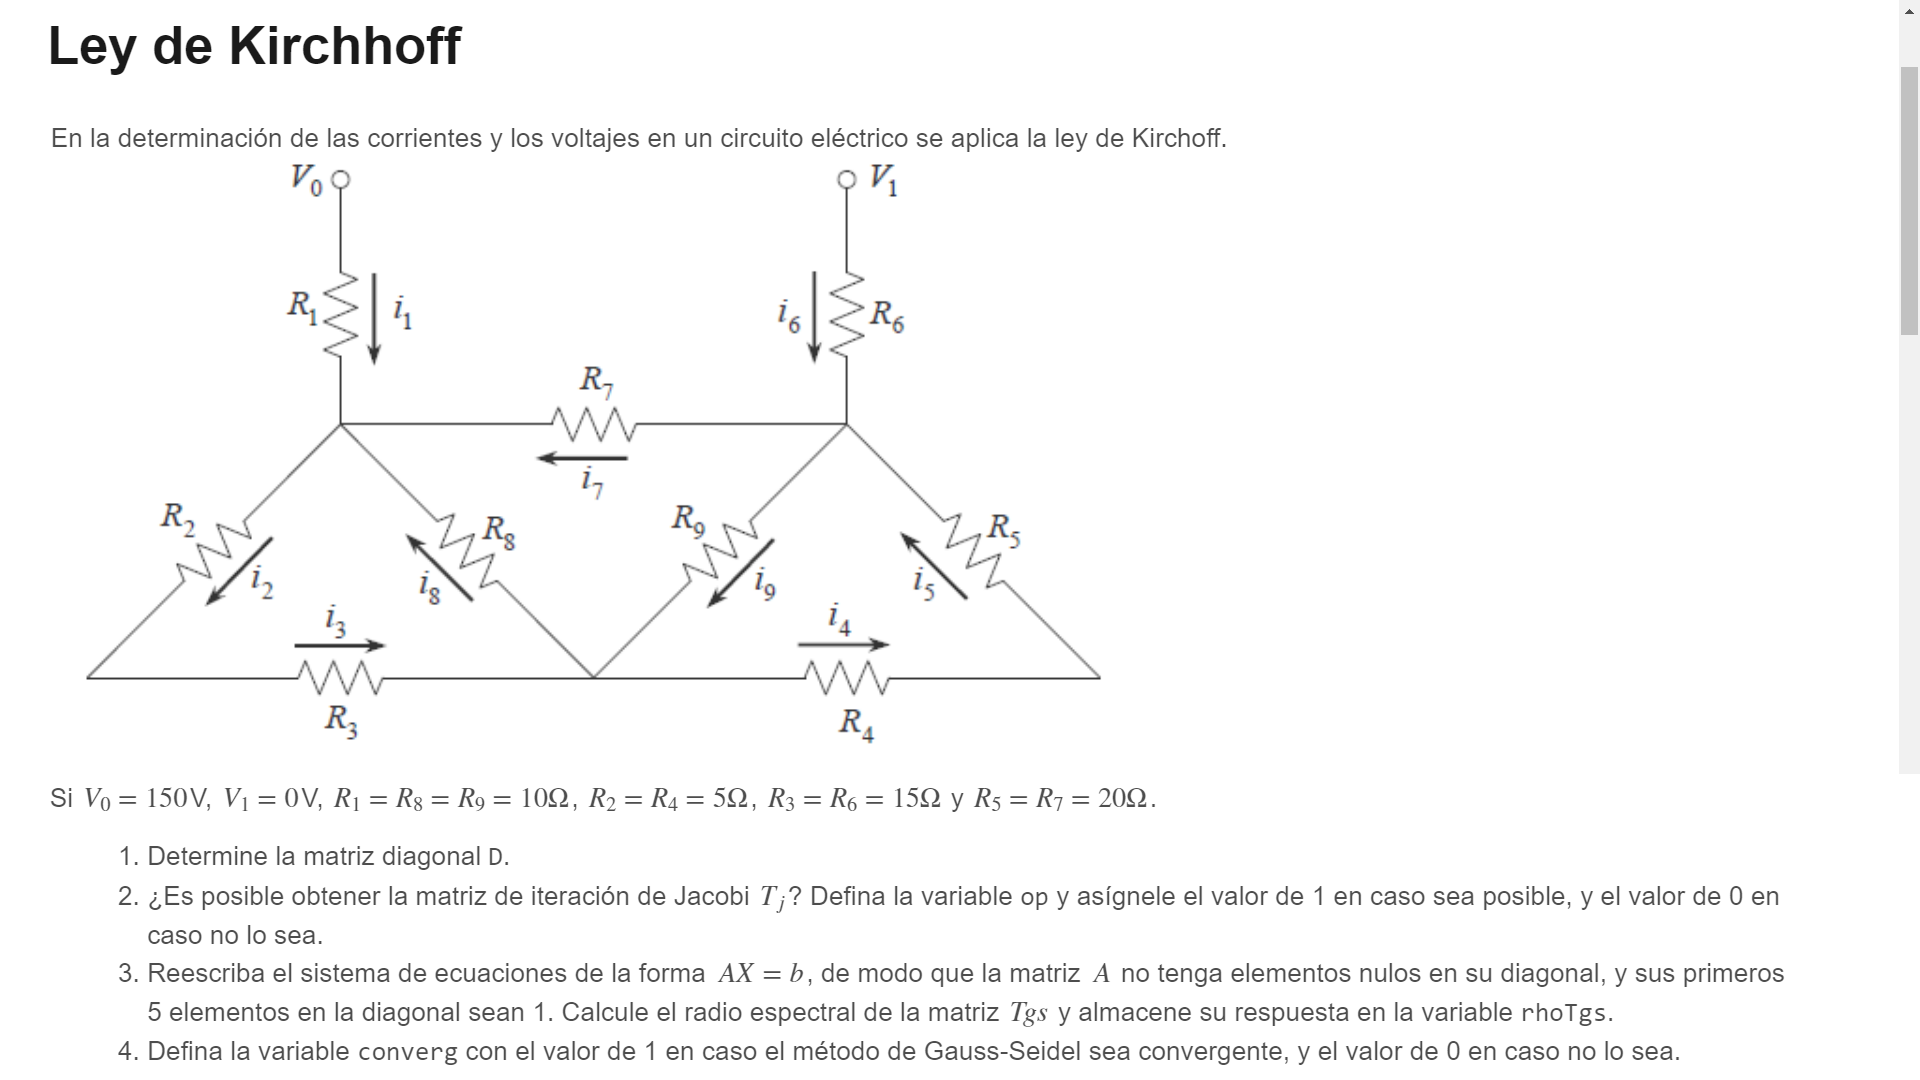

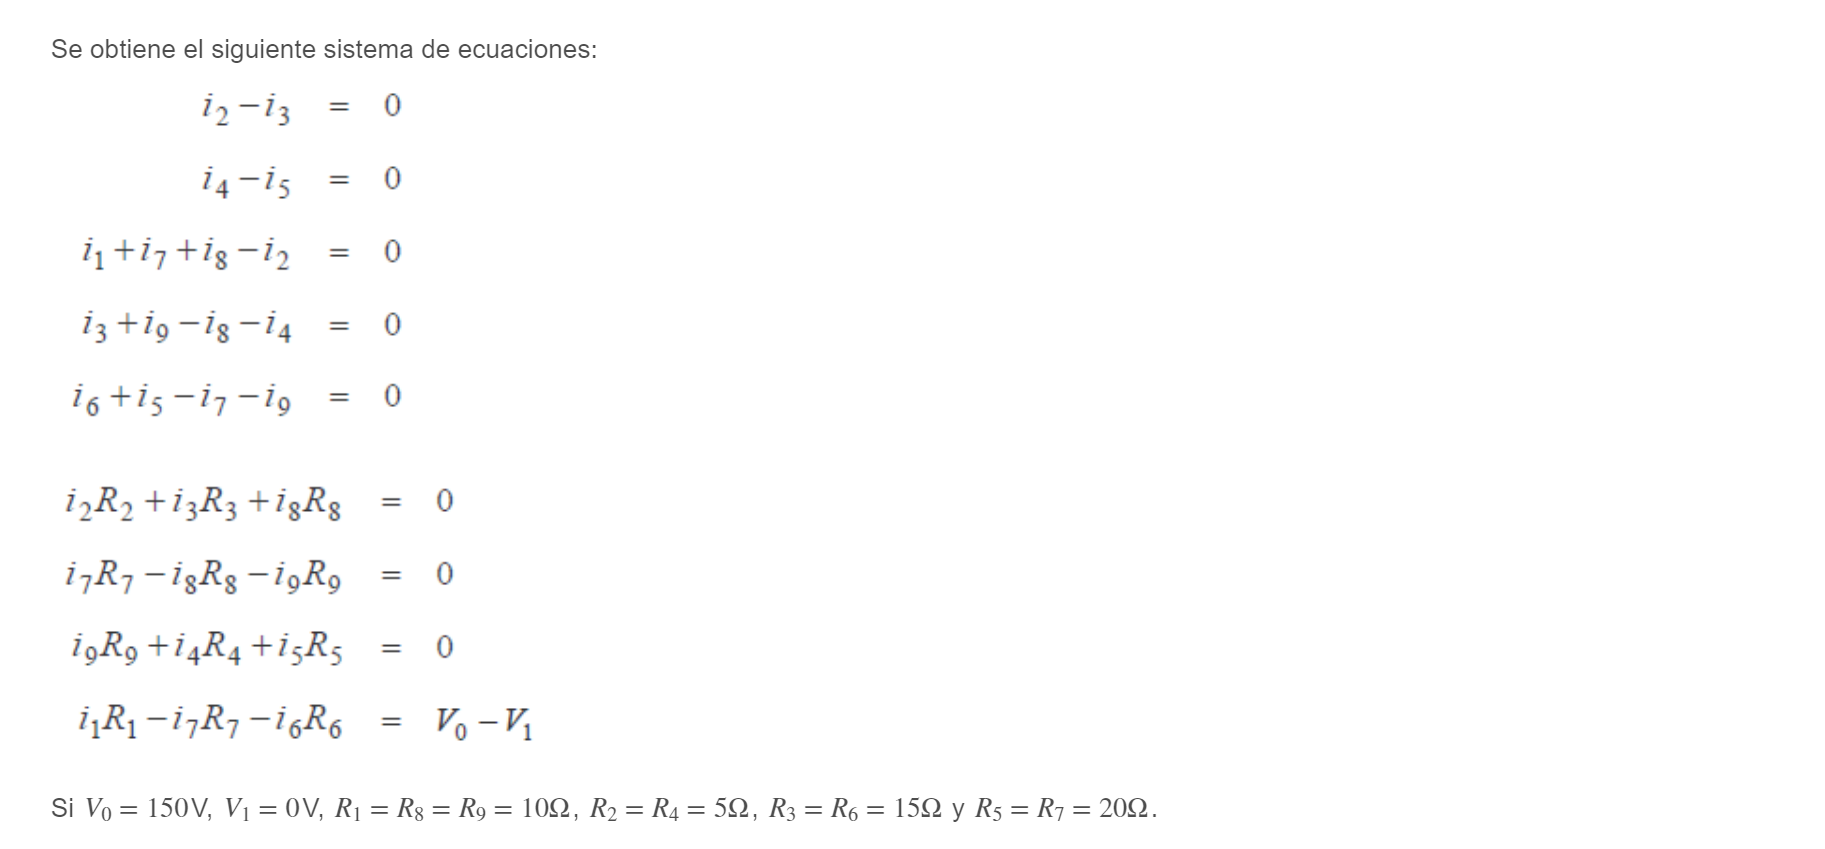

V0=150; V1=0; R1=10; R8=10; R9=10; 
R2=5; R4=5; R3=15; R6=15; R5=20; R7=20; 
A=[0 1 -1 0 0 0 0 0 0;
  0 0 0 1 -1 0 0 0 0;
  1 -1 0 0 0 0 1 1 0;
  0 0 1 -1 0 0 0 -1 1;
  0 0 0 0 1 1 -1 0 -1;
  0 R2 R3 0 0 0 0 R8 0;
  0 0 0 0 0 0 R7 -R8 -R9;
  0 0 0 R4 R5 0 0 0 R9;
  R1 0 0 0 0 -R6 -R7 0 0]

A =      0     1    -1     0     0     0     0     0     0
     0     0     0     1    -1     0     0     0     0
     1    -1     0     0     0     0     1     1     0
     0     0     1    -1     0     0     0    -1     1
     0     0     0     0     1     1    -1     0    -1
     0     5    15     0     0     0     0    10     0
     0     0     0     0     0     0    20   -10   -10
     0     0     0     5    20     0     0     0    10
    10     0     0     0     0   -15   -20     0     0


b=[zeros(8,1); V0-V1] 

b =      0
     0
     0
     0
     0
     0
     0
     0
   150


A \ b

ans =     4.5223
    0.8917
    0.8917
    0.7643
    0.7643
   -4.5223
   -1.8471
   -1.7834
   -1.9108


A =      3    -5     2     0
    -2     5     0     2
     0     1    -3     2
     3     0    10   -28


b =      0
  -200
     0
     0


ans =   -83.8095
  -64.7619
  -36.1905
  -21.9048


## Caso 2

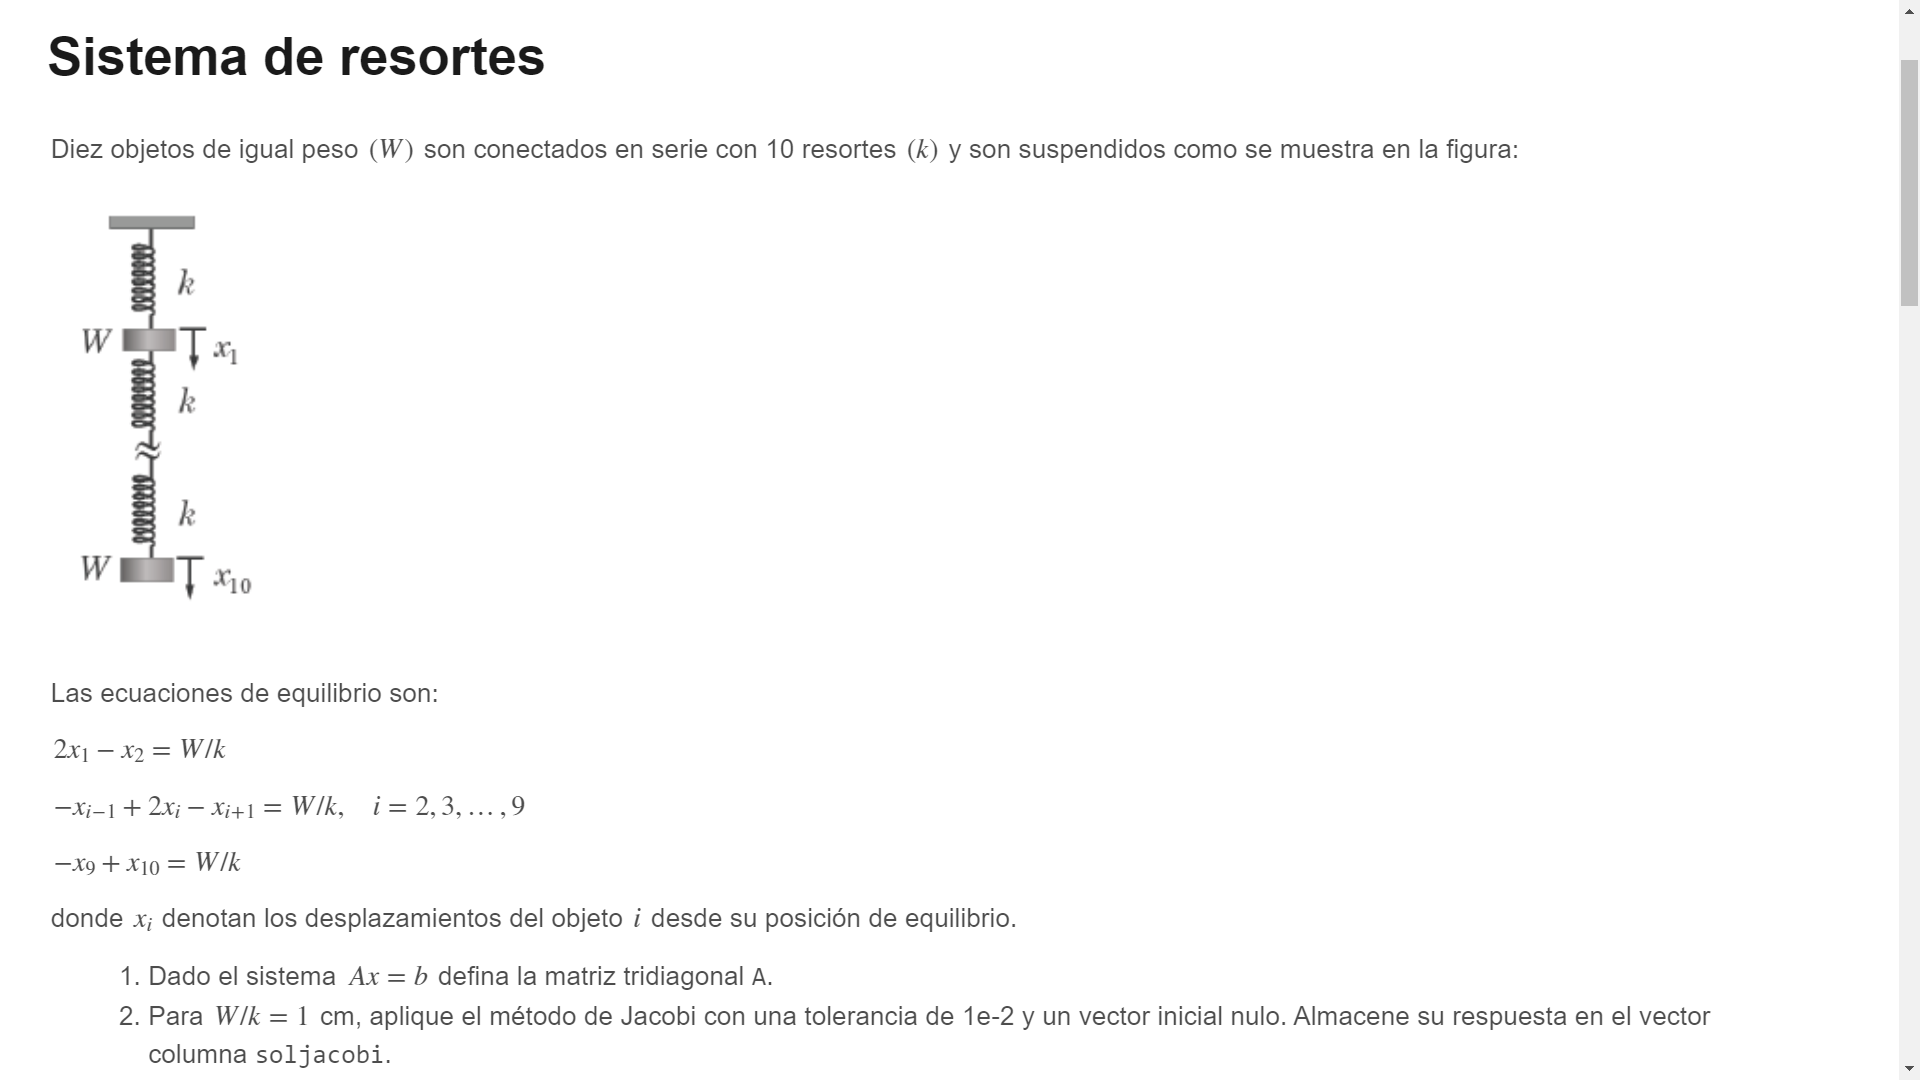

A=diag([2*ones(9,1);1])+diag(-1*ones(9,1),1)+diag(-1*ones(9,1),-1)

A =      2    -1     0     0     0     0     0     0     0     0
    -1     2    -1     0     0     0     0     0     0     0
     0    -1     2    -1     0     0     0     0     0     0
     0     0    -1     2    -1     0     0     0     0     0
     0     0     0    -1     2    -1     0     0     0     0
     0     0     0     0    -1     2    -1     0     0     0
     0     0     0     0     0    -1     2    -1     0     0
     0     0     0     0     0     0    -1     2    -1     0
     0     0     0     0     0     0     0    -1     2    -1
     0     0     0     0     0     0     0     0    -1     1


b=ones(10,1)

b =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


A \ b

ans =    10.0000
   19.0000
   27.0000
   34.0000
   40.0000
   45.0000
   49.0000
   52.0000
   54.0000
   55.0000


diff(A \ b)

ans =     9.0000
    8.0000
    7.0000
    6.0000
    5.0000
    4.0000
    3.0000
    2.0000
    1.0000


## Caso 3

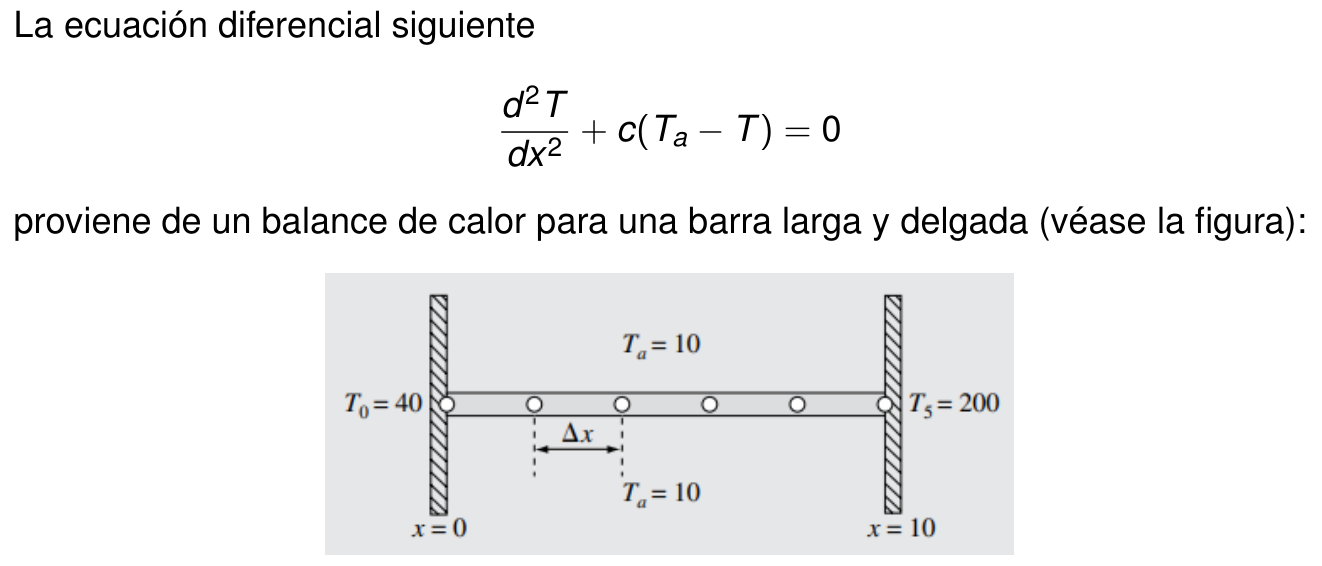

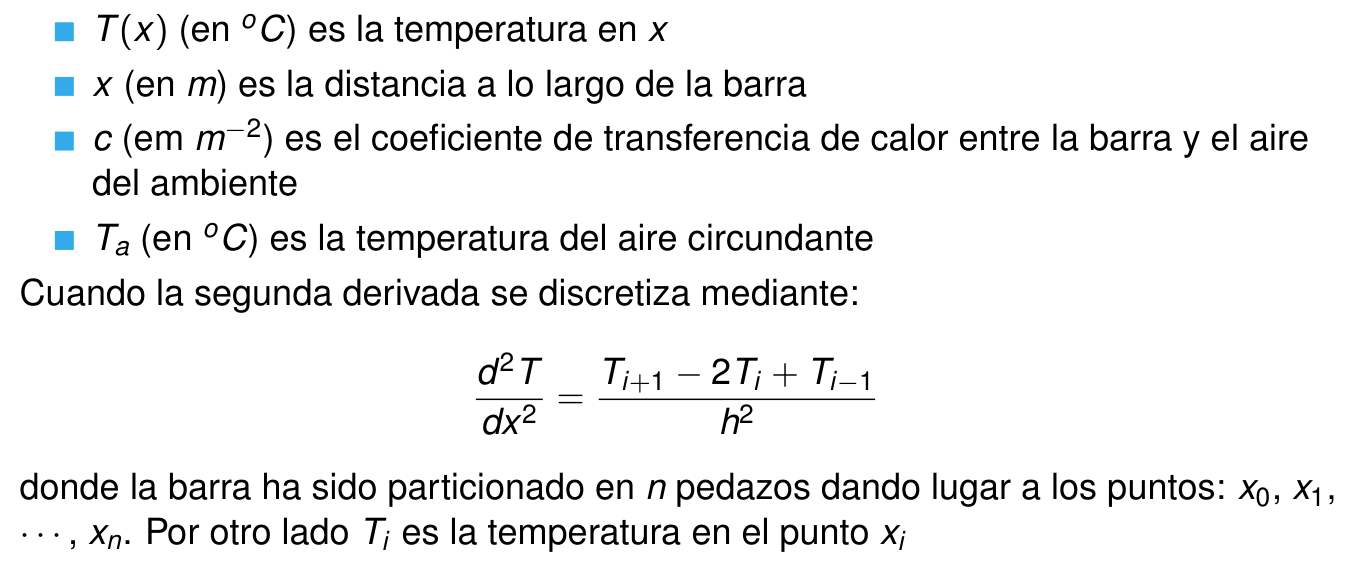

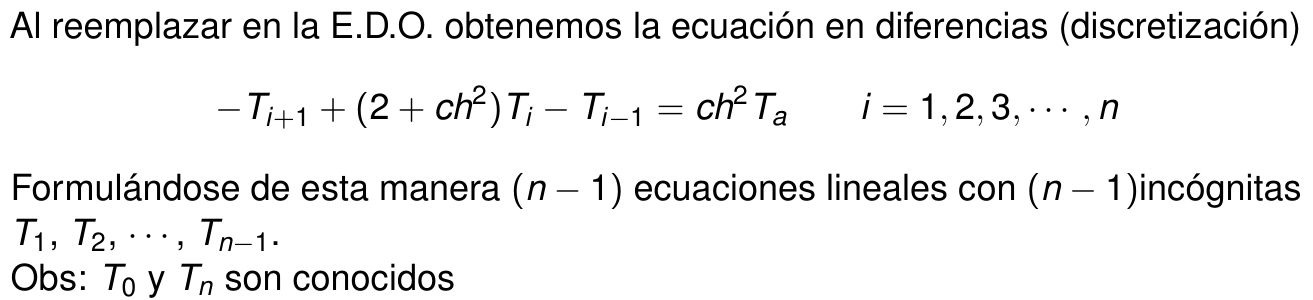

clear

c_dato = 0.0200

% Cálculo simbólico
syms c h Ta
syms T [6 1]
T

$$T = \left(\begin{array}{c} T_{1}\\ T_{2}\\ T_{3}\\ T_{4}\\ T_{5}\\ T_{6} \end{array}\right)$$

A = (2+c*h^2)*eye(4,4)+...
    diag(-1*ones(3,1),-1)+...
    diag(-1*ones(3,1),1)

$$A = \left(\begin{array}{cccc} c\,h^{2}+2 & -1 & 0 & 0\\ -1 & c\,h^{2}+2 & -1 & 0\\ 0 & -1 & c\,h^{2}+2 & -1\\ 0 & 0 & -1 & c\,h^{2}+2 \end{array}\right)$$

b=c*h^2*Ta*ones(4,1)+[T(1) 0 0 T(6)]'

$$b = \left(\begin{array}{c} \mathrm{Ta}\,c\,h^{2}+\bar{T_{1}}\\ \mathrm{Ta}\,c\,h^{2}\\ \mathrm{Ta}\,c\,h^{2}\\ \mathrm{Ta}\,c\,h^{2}+\bar{T_{6}} \end{array}\right)$$

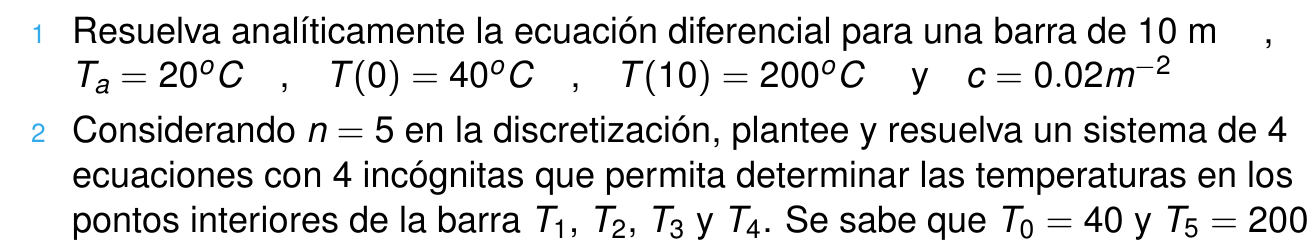

% Datos
Ta_dato=20;
T1_dato=40;
T6_dato=200;
c_dato=0.02
h_dato=(10-0)/5;

% Sol exacta
A = subs(A,[c,h],[c_dato,h_dato])

$$A = \left(\begin{array}{cccc} \frac{52}{25} & -1 & 0 & 0\\ -1 & \frac{52}{25} & -1 & 0\\ 0 & -1 & \frac{52}{25} & -1\\ 0 & 0 & -1 & \frac{52}{25} \end{array}\right)$$

b = subs(b,[c,h,Ta,T(1),T(6)],...
    [c_dato,h_dato,Ta_dato,T1_dato,T6_dato])

$$b = \left(\begin{array}{c} \frac{208}{5}\\ \frac{8}{5}\\ \frac{8}{5}\\ \frac{1008}{5} \end{array}\right)$$

A=double(A); b=double(b);
x_exac = A \ b; x_exac'

ans =    61.0739   85.4338  115.0283  152.2252



% Gauss-Seidel
Tol=1e-5; x0=zeros(4,1);
[z,T,c]=iterativo(A,b,x0,Tol,1); 
disp(table(z(:,1),z(:,2),z(:,3),z(:,4),z(:,5),z(:,6),...
    'VariableNames',{'k','T(2)','T(4)','T(6)','T(8)','error'}))

    k      T(2)      T(4)      T(6)      T(8)       error   
    __    ______    ______    ______    ______    __________

     0         0         0         0         0           NaN
     1        20    10.385    5.7618    99.693             1
     2    24.993    15.555    56.177    123.93        0.4068
     3    27.478    40.988    80.057    135.41       0.18782
     4    39.706    58.348    93.923    142.08       0.12218
     5    48.052    69.026    102.26    146.09      0.073098
     6    53.186    75.504     107.3    148.51      0.043615
     7      56.3    79.425    110.35    149.98      0.026144
     8    58.185    81.797     112.2    150.87      0.015728
     9    59.326    83.233    113.32     151.4     0.0094838
    10    60.016    84.102    113.99    151.73     0.0057267
  

Funciones de usuario

function [z,T,c]=iterativo(A,b,x0,Tol,method)
% Entrada
% method: variable numérica
% method=0: Jacobi
% method=1: Gauss-Seidel

% Construir T, c
D=diag(diag(A));
L=-tril(A,-1);
U=-triu(A,1);

if method==0
    % Jacobi
    T=inv(D)*(L+U);
    c=inv(D)*b;
elseif method==1
    % Gauss-Seidel
    T=inv(D-L)*(U);
    c=inv(D-L)*b;    
else
    error('Escoja un método válido: 0 (Jacobi), 1 (Gauss-Seidel)')
end

% Inicialización
k=0;
er=1;
z=[k x0' NaN];

while er > Tol
    k=k+1;
    x1=T*x0+c;
    er=norm(x1-x0,inf)/norm(x1,inf);
    z=[z;k x1' er];
    x0=x1;
end
end

function op=diagdom(A)
% Salida
% op=1: diagonal estrictamente dominante
% op=0: no diagonal estrictamente dominante
    op=double(all( 2*diag(abs(A)) > sum(abs(A),2) ));
end

function [op,r]=convergente(A,method)
% Entrada
% method=0: Jacobi
% method=1: Gauss-Seidel
% Salida
% op=1: convergente
% op=0: no convergente

% Construir T, c
D=diag(diag(A));
L=-tril(A,-1);
U=-triu(A,1);

if method==0
    T=inv(D)*(L+U); % Jacobi
elseif method==1
    T=inv(D-L)*(U); % Gauss-Seidel
end

r = max(abs(eig(T)));
op = double(r < 1);
end
